# inpainting RobustPCA example: moon picture corrupted with some text

addpath('../');

% read image and add the mask

img = double(imread('F.jpg'))/255;%【moon.tif怎么弄来的？】
img = img(750:749+512, 800:799+1024);%取了512×1024的大小
msk = zeros(size(img));%与img等大小
msk(65:320,65:320) = imread('text.png');
%msk的4773处写入文字，其他地方都为0
img_corrupted = img;
img_corrupted(msk > 0) = nan;%满足条件替换
%【msk>0是一个含0和1的矩阵，替换的方法】
% img_corrupted是img除去4773处毁坏值剩下的部分
% 1.img（512×1024）原图
% 2.msk（512×1024）中间一块256×256的区域有1138个像素装了text剩下为0的矩阵
% 3.img_corrupted（512×1024）is 原图img with 4773 nan values
fprintf(1, '%d corrupted entries\n', nnz(isnan(img_corrupted)));

4773 corrupted entries



% create a matrix X from overlapping patches用重叠小块构造X（其实这个X就是特征矩阵F）
ws = 16; % window size正方形小块的边长
no_patches1 = size(img, 1) / ws;
no_patches2 = size(img, 2) / ws;
%size(img，1)返回img_corrupted的行数
%no_patches1记录的是patches无重叠时img行数对ws的倍数
%no_patches2记录的是patches无重叠时img列数对ws的倍数
%size(imread(img_corrupted))=[no_patches1*ws, no_patches2*ws]
X = zeros(2,ws^2);%行数是不是2都无所谓，这个2可以是任何数字（试出来的）
k = 1;
for i = (1:no_patches1*2-1)%横向（32+31（重叠部分））块
    for j = (1:no_patches2*2-1)%纵向（64+63（重叠部分））块
        r1 = 1+(i-1)*ws/2:(i+1)*ws/2;%每次为ws的一半一半取值
        r2 = 1+(j-1)*ws/2:(j+1)*ws/2;%每次为ws的一半一半取值
        patch = img_corrupted(r1, r2);
        %r1长度为ws，但是有（32+31（重叠部分））块，是overlapping
        % r2长度为ws，也是overlapping，（64+63（重叠部分））块
        X(k,:) = patch(:);
        %【注意到这里的F（特征矩阵）是重叠部分取出来的】
        %【把（32+31（重叠部分））×（64+63（重叠部分））个patches】
        % 写入X的((32+31)*(64+63)=8001)行的每一行中
        k = k + 1;
    end
end

% apply Robust PCA
lambda = 0.02; % close to the default one, but works better
% 确实0.02这个值works best
tic
[L, S] = RobustPCA(X, lambda, 1.0, 1e-5);

iter: 0001	err: 0.010253	rank(L): 238	card(S): 69887
iter: 0010	err: 0.000971	rank(L): 249	card(S): 298718
iter: 0020	err: 0.000194	rank(L): 256	card(S): 326458
iter: 0030	err: 0.000090	rank(L): 256	card(S): 333092
iter: 0040	err: 0.000052	rank(L): 256	card(S): 335558
iter: 0050	err: 0.000034	rank(L): 256	card(S): 336693
iter: 0060	err: 0.000023	rank(L): 256	card(S): 337092
iter: 0070	err: 0.000017	rank(L): 256	card(S): 337350
iter: 0080	err: 0.000013	rank(L): 256	card(S): 337450
iter: 0090	err: 0.000010	rank(L): 256	card(S): 337522
iter: 0092	err: 0.000010	rank(L): 256	card(S): 337498


toc

时间已过 57.138000 秒。


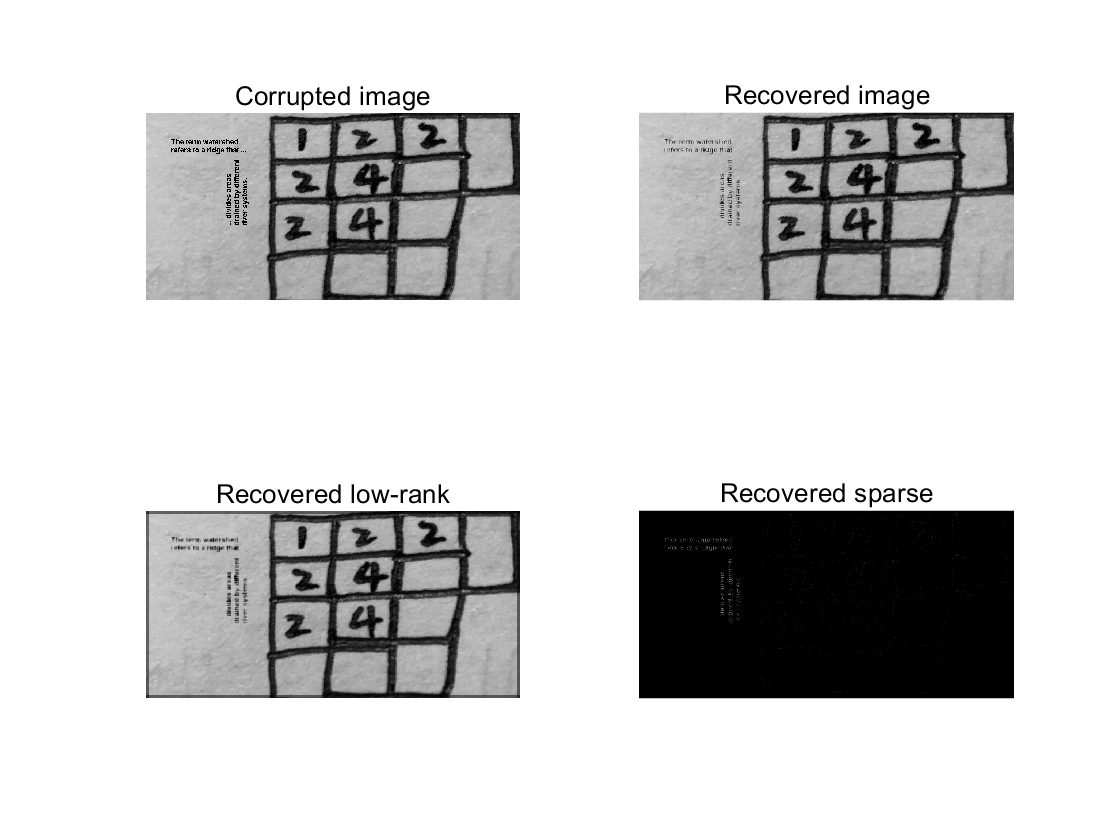


% reconstruct the image from the overlapping patches in matrix L
img_reconstructed = zeros(size(img));
img_noise = zeros(size(img));
k = 1;
for i = (1:no_patches1*2-1)
    for j = (1:no_patches2*2-1)
        % average patches to get the image back from L and S
        % todo: in the borders less than 4 patches are averaged
        patch = reshape(L(k,:), ws, ws);
        r1 = 1+(i-1)*ws/2:(i+1)*ws/2;
        r2 = 1+(j-1)*ws/2:(j+1)*ws/2;
        img_reconstructed(r1, r2) = img_reconstructed(r1, r2) + 0.25*patch;
        %img_reconstructed为low-rank部分，并且恢复者中含有nan
        patch = reshape(S(k,:), ws, ws);
        img_noise(r1, r2) = img_noise(r1, r2) + 0.25*patch;
        %img_noise为sparse部分，并且恢复者中含有nan
        %【F恢复为X的过程】
        k = k + 1;
    end
end
img_final = img_reconstructed;
img_final(~isnan(img_corrupted)) = img_corrupted(~isnan(img_corrupted));

% show the results
figure;
subplot(2,2,1), imshow(img_corrupted), title('Corrupted image')
%原图img中text处（4773个像素）被抠掉剩下的部分
subplot(2,2,2), imshow(img_final), title('Recovered image')
%恢复的图像=原图（未毁坏处）+低秩矩阵（毁坏处）
subplot(2,2,3), imshow(img_reconstructed), title('Recovered low-rank')
%低秩矩阵=img_corrupted变为patches后分解L+S的L部分reshape成的低秩矩阵
%稀疏矩阵=img_corrupted变为patches后分解L+S的S部分reshape成的稀疏矩阵
subplot(2,2,4), imshow(img_noise), title('Recovered sparse')%加阈值kmeans


fprintf(1, 'ws=%d\tlambda=%f\trank(L)=%d\tcard(S)=%d\terr=%f\n', ...
    ws, lambda, rank(L), nnz(S), norm(img - img_final, 'fro'));

ws=16	lambda=0.020000	rank(L)=256	card(S)=356205	err=24.786838
